##  МИУ

close all;
clear variables;

Включить доп формулы 

On = -1;

Входные параметры

%  1 - входные данные 
k0 = 2*pi;
% Параметры среды-1
e1 = 4;
mu1 = 1;
k1 = k0*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1);

% Параметры среды-2
k2 = k0;
eta2 = 120*pi;

% Параметры программы
% N = 30; % количество точек на круга
% полуоси элипса

% a = 1/2; % вертикаль (РАЗМЕР)
% b = a; % горизонталь (РАЗМЕР)

phi_i_grad = 0; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]
gamma = 1.781072417990;

mass_a = 0.3 : 0.0025 : 1;
% mass_a  = 5/(2*pi);
% mass_a = 0.4 : 0.1 : 1;
for s = 1 : length(mass_a)
    a = mass_a(s)
    b = a;
    % выбираем количество источников
    N = round(a*10)*10; 

Генервция dx

    dx_b = b/N;
    dx_a = a/N;

Генерация точек

    % генератора координат для первого участка
    dx_mass = zeros(1, 4*N);
    for n= 1 : N
        % горизонт 1
        x1(n) = (n-0.5)*dx_b;
        z1(n) = 0;
        % вертикаль 1
        x2(n) = b;
        z2(n) = (n-0.5)*dx_a;
        % горизонт 2
        x3(n) = (n-0.5)*dx_b;
        z3(n) = a;
        % вертикаль 2
        x4(n) = 0;
        z4(n) = (n-0.5)*dx_a;  
        
        % сразу заполним dx
        dx_mass(n) = dx_b;
        dx_mass(n+N) = dx_a;
        dx_mass(n+2*N) = dx_b;
        dx_mass(n+3*N) = dx_a;
    end

a = 0.4000

a = 0.5000

a = 0.6000

a = 0.7000

a = 0.8000

a = 0.9000

a = 1

    % координта на поверхности цилиндра
    x_midle = [x1 x2 fliplr(x3) x4];
    z_midle = [z1 z2 z3 fliplr(z4)];
    
%     plot(x_midle,z_midle)

Расчет касательных к отрезкам разибения

    % касательные * до копирования
    tx_one = [-1 0 1 0];
    tz_one = [0 -1 0 1];
    
    %  общие касательный
    tz = [repmat(tz_one(1),1,N) repmat(tz_one(2),1,N) repmat(tz_one(3),1,N) repmat(tz_one(4),1,N)];
    tx = [repmat(tx_one(1),1,N) repmat(tx_one(2),1,N) repmat(tx_one(3),1,N) repmat(tx_one(4),1,N)];

Посчитаем n для каждого отрезка

    %   нормальный вектор найдем с помощью матрицы повороты
        alpha = -90;
        matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];
    
    for i = 1 : 4*N
         matrix_temp = [tx(i), tz(i)]*matrix;
         nx(i) = matrix_temp(1);
         nz(i) = matrix_temp(2);
    end
    
    

    % ========================================================================
    % 3 - cам ходя расчета 
    % списик для хранения элементов системы 
    Z = zeros(8*N,8*N);
    Y = zeros(8*N,8*N);
        
    for m  = 1 : 4*N
        xm = x_midle(m);
        zm = z_midle(m);
        txm = tx(m);
        tzm = tz(m);
        nxm = nx(m);
        nzm = nz(m);
        
        for n = 1 : 4*N
            xn = x_midle(n);
            zn = z_midle(n);
            txn = tx(n);
            tzn = tz(n);
            nxn = nx(n);
            nzn = nz(n);
            dx = dx_mass(n);
                
            % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
            x_mO2 = xm - xn;
            z_mO2 = zm - zn;
            
            % Положим этот вектор на новую СК
            % Координаты этой точки (в ЛСК)
            umn = x_mO2*txn + z_mO2*tzn;
            wmn = x_mO2*nxn + z_mO2*nzn;
            
            
            % локальные замены 
            xmn = xm - xn;
            zmn = zm - zn;
            r = sqrt(xmn^2 + zmn^2);
            
            umn_plus = umn + dx/2;
            umn_minus = umn - dx/2; 
            r_minus = sqrt(umn_minus^2 + wmn^2);
            r_plus = sqrt(umn_plus^2 + wmn^2);
            rmn = sqrt(umn^2 + wmn^2);
            
            if n == m
                % cоставляющие Hy1
                he_y1 =  +1/2;
                % cоставляющие Hy2  
                he_y2 = -1/2;
                % cоставляющие E1u
                fe_u12 = 1i/4*dx*(1 + 1i*2/pi*(log(gamma*k2*dx/4)-1));
                % cоставляющие E2u
                fe_u22 = 1i/4*dx*(1 + 1i*2/pi*(log(gamma*k2*dx/4)-1));   
            elseif abs(n-m) <= 1.5*On
               % МАГНИТНОЕ ПОЛЕ
                % cоставляющие Hy1
                he_y1 =  - (1i/8*wmn*k1^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)));
                hm_y1 = dx + 2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
                + umn_plus*log(gamma*k1/2*sqrt(umn_plus^2+wmn^2))...
                - umn_minus*log(gamma*k1/2*sqrt(umn_minus^2+wmn^2)) - dx);
                hm_y1 = hm_y1 * 1i/4; % домножение на коэфицент
                % cоставляющие Hy2  
                he_y2 = - (1i/8*wmn*k2^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)));
                hm_y2 = dx + 2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
                + umn_plus*log(gamma*k2/2*sqrt(umn_plus^2+wmn^2))...
                - umn_minus*log(gamma*k2/2*sqrt(umn_minus^2+wmn^2)) - dx);
                hm_y2 = hm_y2 * 1i/4; % домножение на коэфицент
               % ЭЛЕКТРИЧЕСКОЕ ПОЛЕ
                % cоставляющие E1u
                fe_u12 = hm_y1;
                fm_u1 = he_y1; 
                % cоставляющие E2u
                fe_u22 = hm_y2;
                fm_u2 = he_y2; 
            else
                % cоставляющие Hy1
                he_y1 = - 1i/4*k1*dx*(wmn/rmn*H(1,k1*rmn));
                % cоставляющие Hy2  
                he_y2 = - 1i/4*k2*dx*(wmn/rmn*H(1,k2*rmn));
                % cоставляющие E1u
                fe_u12 = 1i/4*dx*H(0,k1*rmn);
                % cоставляющие E2u
                fe_u22 = 1i/4*dx*H(0,k2*rmn);
            end
            
          % магнитное поле
            % cоставляющие H1u
            fe_u11 = - 1i/4*k1*(umn_plus/r_plus*H(1,k1*r_plus) - umn_minus/r_minus*H(1,k1*r_minus));
            % cоставляющие H2u
            fe_u21 = - 1i/4*k2*(umn_plus/r_plus*H(1,k2*r_plus) - umn_minus/r_minus*H(1,k2*r_minus));
            % cоставляющие H1w
            fe_w1 = - 1i/4*k1*(wmn/r_plus*H(1,k1*r_plus) - wmn/r_minus*H(1,k1*r_minus));
            % cоставляющие H2w
            fe_w2 = - 1i/4*k2*(wmn/r_plus*H(1,k2*r_plus) - wmn/r_minus*H(1,k2*r_minus));
                   
            %% СОБЕРЕМ ВСЕ ВМЕСТЕ
            % cоставляющие Hy1
            H1y = he_y1;
            % cоставляющие Hy2  
            H2y = he_y2;
            % cоставляющие E1u
            E1u = 1i*eta1/k1*(fe_u11 + k1^2*fe_u12);
            % cоставляющие E2u
            E2u = 1i*eta2/k2*(fe_u21 + k2^2*fe_u22);
            % cоставляющие E1w
            E1w = 1i*eta1/k1*fe_w1;
            % cоставляющие E2w
            E2w = 1i*eta2/k2*fe_w2;  
            
            % элементы системы       
            H1mn = H1y;
            H2mn = -H2y;
            
            dot_tm_tn = (txm*txn+tzm*tzn);
            dot_tm_nn = (txm*nxn+tzm*nzn);
            
            E1mn = dot_tm_tn*E1u + dot_tm_nn*E1w;
            E2mn = -(dot_tm_tn*E2u + dot_tm_nn*E2w);
            
            % запись в массив для дальнешего решения 
            Z(m,n) = E1mn;
            Z(m,n+4*N) = E2mn;
            Z(m+4*N,n) = H1mn;
            Z(m+4*N,n+4*N) = H2mn;
        end
    end
    
    
    E = zeros(4*N,1);
    % падающее поле 
    for m = 1 : 4*N
        xm = x_midle(m);
        zm = z_midle(m);
        txm = tx(m);
        tzm = tz(m);
    
        % cоставляющие полей
        cx = -1i*k2*cosd(phi_i_grad);
        cz = -1i*k2*sind(phi_i_grad);
        
        Hiy = exp(cx*xm+cz*zm);
        Eix = - eta2*sind(phi_i_grad) * Hiy;
        Eiz = + eta2*cosd(phi_i_grad) * Hiy;
        
        % элементы системы  
        Hi = Hiy;
        Ei = txm*Eix + tzm*Eiz;
    
        % запись в массив для дальнешего решения 
        E(m) = Ei;
        E(m+4*N) = Hi;
    end    
    
    % Расчитаем токи
    % тут зашито сразу 2 тока
    I = Z\E;     
    
    % отделим один ток от другого
    j1 = I(1:4*N);
    j2 = I(4*N+1:8*N);

    % построим эти графики 
%     plot(phi_circl_grad,  abs(j1), 'r',phi_circl_grad, abs(j2), 'b');

## ЭПР

    for p = 1
        Sum_H = 0;
        phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
        phi_for_graf_DA(p) = (p-1)/2; % угол для графика
        
        cx = - 1i*k2*cosd(phi);
        cz = - 1i*k2*sind(phi);

        for n = 1 : 4*N
            txn = tx(n);
            tzn = tz(n);
            xn = x_midle(n);
            zn = z_midle(n);
            dx = dx_mass(n);
            
            Sum_H = Sum_H + k2*dx/4*j2(n)*(txn*sind(phi) - tzn*cosd(phi))*exp(cx*xn+cz*zn);
        end
        
        RCS = 10*log10((4/k2)*Sum_H*conj(Sum_H));
    end

    RCS_a(s) = RCS;
end

figure;
plot(mass_a, RCS_a,'r-');

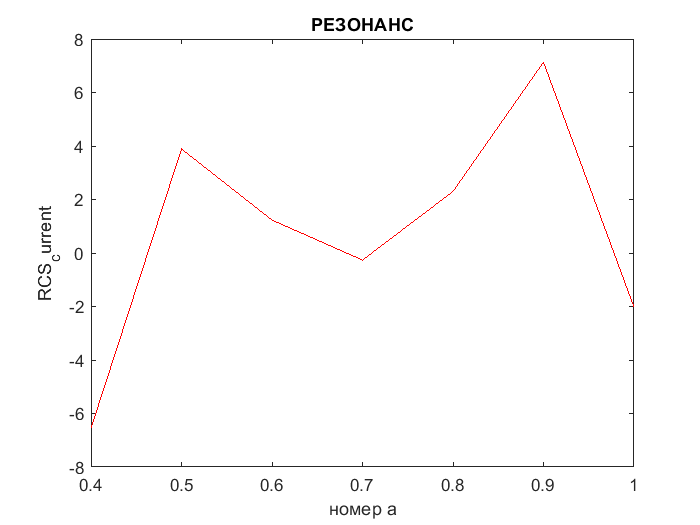

title('РЕЗОНАНС'); 
xlabel('номер а'); 
ylabel('RCS_current');

name_file = strcat('REZ_MIE_Ae_sqrt_Hpol_', num2str(length(mass_a)),'.dat');
f03 = fopen(name_file,'w');

% за максимум Y примем значения в центре передней стороны падения

for n= 1 : length(mass_a)
    fprintf(f03,' %10.5f %10.5f\n', mass_a(n), RCS_a(n));
end

fclose(f03);

Проверка ЭПР (делается 1 раз)

## ЭПР

for p = 1 : 721
    Sum_H = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k2*cosd(phi);
    cz = - 1i*k2*sind(phi);
    

        for n = 1 : 4*N
            txn = tx(n);
            tzn = tz(n);
            xn = x_midle(n);
            zn = z_midle(n);
            dx = dx_mass(n);
            
            Sum_H = Sum_H + k2*dx/4*j2(n)*(txn*sind(phi) - tzn*cosd(phi))*exp(cx*xn+cz*zn);
        end
    
    RCS(p) = 10*log10((4/k2)*Sum_H*conj(Sum_H));
    SIGMA(p) = (4/k2)*Sum_H*conj(Sum_H);


end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA, RCS,'r-');

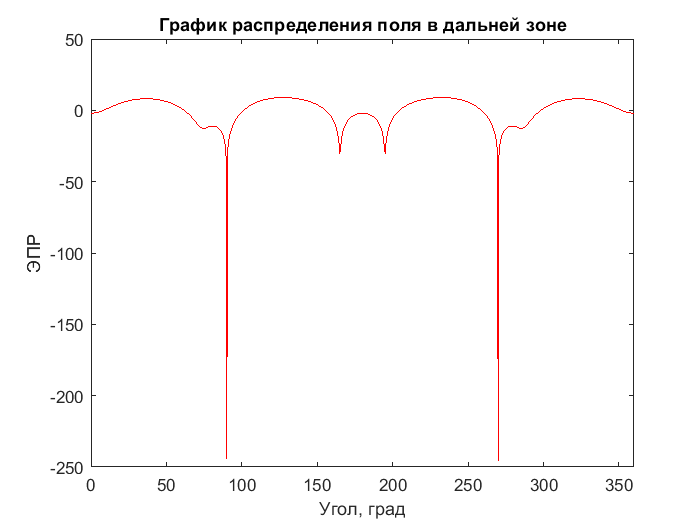

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

### Магнитное поле на поврехности 

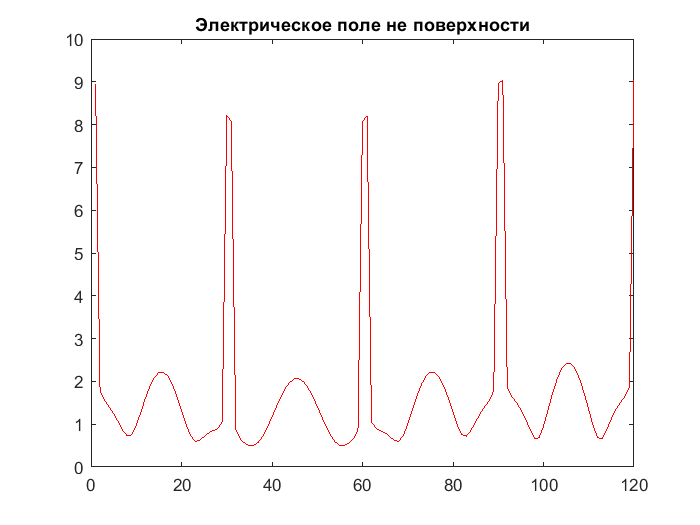

% номера ВИ для графика 
n_for_graf = zeros(1, 4*N);
for i = 1 : 4* N
     n_for_graf(i) = i;
end

%% МАГНИТНОЕ Поле на поврехности 
H_surf = zeros(N, 1); 
for m  = 1 : 4*N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    n_for_graf(m) = m; % для графика
    
    
    H_surf_n = 0;
    for n = 1 : 4*N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);   
        
        if n == m
            % электрическое поле
            he_y2 = -1/2;
        elseif abs(n-m) <= 1.5*On
           % МАГНИТНОЕ ПОЛЕ
            % cоставляющие Hy2  
            he_y2 = - (1i/8*wmn*k2^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)));
            hm_y2 = dx + 2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k2/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k2/2*sqrt(umn_minus^2+wmn^2)) - dx);
            hm_y2 = hm_y2 * 1i/4; % домножение на коэфицент
        else
            % электрчиеское поле
            he_y2 = - 1i/4*k2*dx*(wmn/rmn*H(1,k2*rmn));
        end
        H2y = he_y2;
        H_surf_n = H_surf_n + j2(n) * H2y;
    end
    
    H_surf(m) =  H_surf_n; 
 end
 
figure;
plot(n_for_graf, abs(H_surf), 'r');
title('Магнитное поле не поверхности');  

function [H_calc] = H(n,x)
    H_calc = besselh(n,1,x); 
end

function [J_calc] = J(n,x)
    J_calc = besselJ(n,x); 
end
    
function [dJ_calc] = dJ(n,x)
    dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
end

function [dH_calc] = dH(n,x)
    dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
end
